Copyright © 2021  Shababuddin Khan || sk@pcampus.edu.np

*Department of Electrical Engineering, *[Pulchowk Campus](https://pcampus.edu.np/)*, Tribhuwan University, Nepal*

A Series of  Module has been designed and developed by author mentioned above with full copyright for a course of **Control System** to demonstrante the concept of control system and its implementation in real life to second year Aerospace engineering students at Tribhuwan University.

# ***MODULE 4: Time Response of Control System***

Time Response Analysis is the response given by the system which is function of the time, to the applied excitation is called time response of a control system. The **time response** represents how the state of a dynamic system changes in time when subjected to a particular input. The time response of a linear dynamic system consists of the sum of the **transient response** which depends on the initial conditions and the **steady-state response** which depends on the system input.  

# **4.1 Standard Test Signal**

Those signals which are most commonly used as reference inputs to the system are defined as **Standard Test Inputs.** They are:

- A sudden change  **[Step Signal] **

- A momentary shock **[Impulse Signal]**

- A constant velocity **[Ramp Signal]**

- A constant acceleration **[Parabolic Signal]**

% Standard Test Signal in MATLAB
%time 
dt=0.01;
t = (-1:dt:1)';

% Defining the signal
impulse = t==0;         % If t==0, we have 1
unitstep = t>=0;        % If t>0, We have 1
ramp = t.*unitstep;     % ramp= t *. unit [Scalar Product]
quad = t.^2.*unitstep;  % quad=t *.ramp

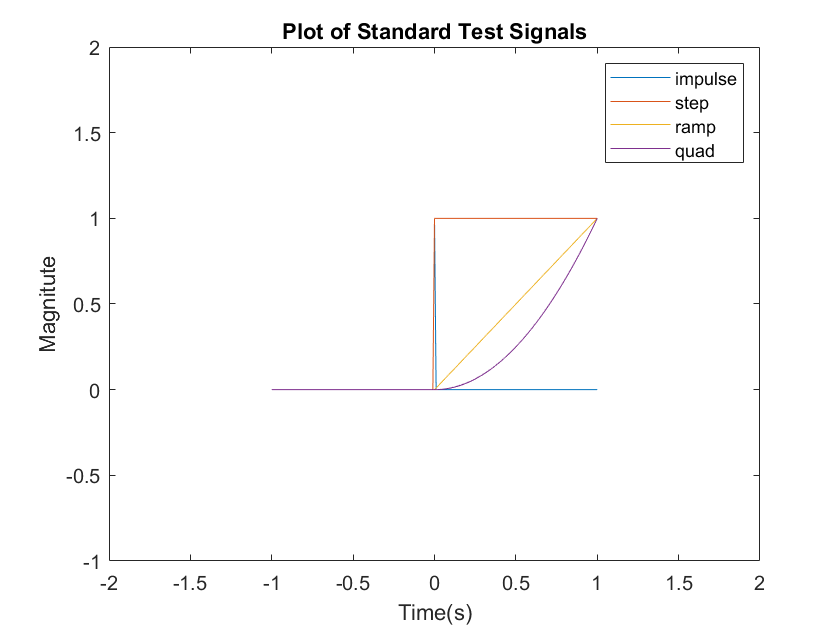

%Plotting the signal
plot(t,[impulse unitstep ramp quad])
% xlim([-2 2])
% ylim([-1 2])
legend impulse step ramp quad

title('Plot of Standard Test Signals')
xlabel('Time(s)')
ylabel('Magnitute')

# 4.2 Laplace Transform of Test Signal

syms A t
unitstep=t/t;
ramp=A*t;
quad=A*t^2/2;

u=A*laplace(unitstep);
r=laplace(ramp);
p=laplace(quad);
u

$$u = \frac{A}{s}$$

r

$$r = \frac{A}{s^{2}}$$

p

$$p = \frac{A}{s^{3}}$$

# 4.3 Time Response of First Order System with different Sources


$$G\left(s\right)=\frac{10}{s+10}$$


## 4.3.1 With Step Input

% Defining the System
syms s;
G1=10/(s+10);    

% For Step Signal 
A=6;
R=A/s;
r=ilaplace(R);

% Output in s-Domain
C1=G1*R;
% Output in Time Domain
c1=ilaplace(C1)

$$c1 = 6-6\,{\mathrm{e}}^{-10\,t}$$

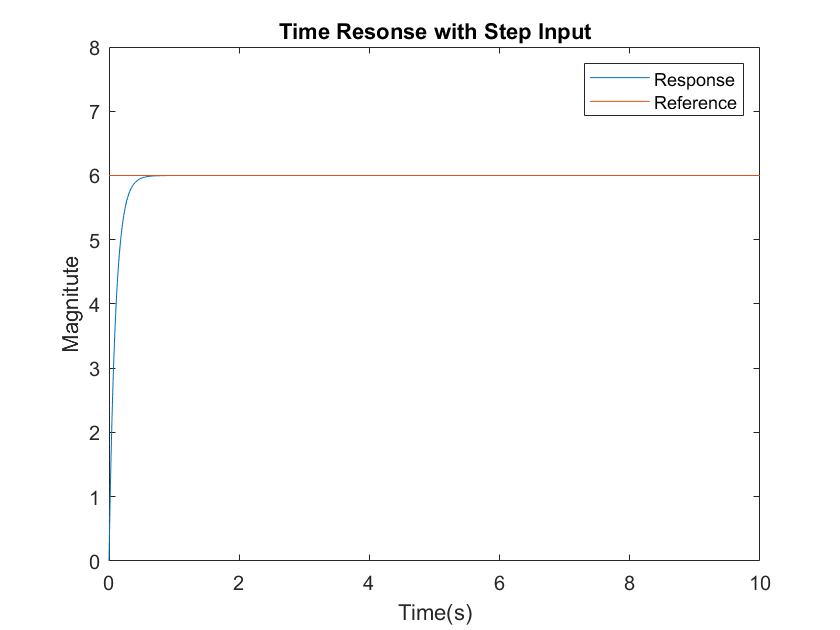


%Time Response of System
figure
fplot(c1,[0,10]);
hold on
fplot(r,[0,10]);
hold off
xlabel('Time(s)');
ylabel('Magnitute');
title('Time Resonse with Step Input');
legend Response Reference;
ylim([0,8])

## 4.3.2 With Ramp Input

% Defining the System
syms s;
G1=10/(s+10);    

% For Ramp Signal 
A=1;
R=A/s^2;
r=ilaplace(R);

% Output in s-Domain
C1=G1*R;
% Output in Time Domain
c1=ilaplace(C1)

$$c1 = t+\frac{{\mathrm{e}}^{-10\,t}}{10}-\frac{1}{10}$$

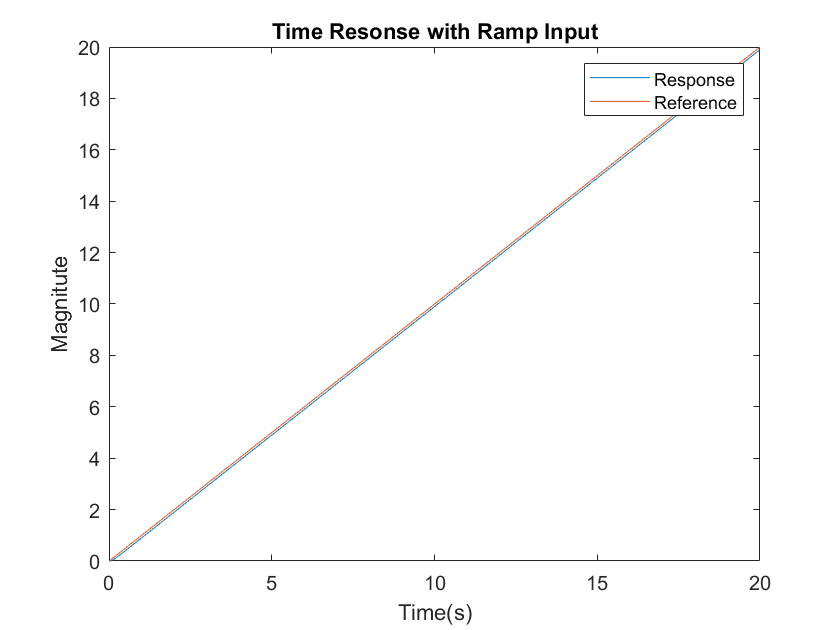


%Time Response of System
figure
fplot(c1,[0,20]);
hold on
fplot(r,[0,20]);
hold off
xlabel('Time(s)');
ylabel('Magnitute');
title('Time Resonse with Ramp Input');
legend Response Reference;

## 4.3.3 With Parabolic Input

% Defining the System
syms s;
G1=10/(s+10);

% For Parabolic Signal 
A=1;
R=A/s^3;
r=ilaplace(R);

% Output in s-Domain
C1=G1*R;
% Output in Time Domain
c1=ilaplace(C1)

$$c1 = \frac{t^{2}}{2}-\frac{{\mathrm{e}}^{-10\,t}}{100}-\frac{t}{10}+\frac{1}{100}$$

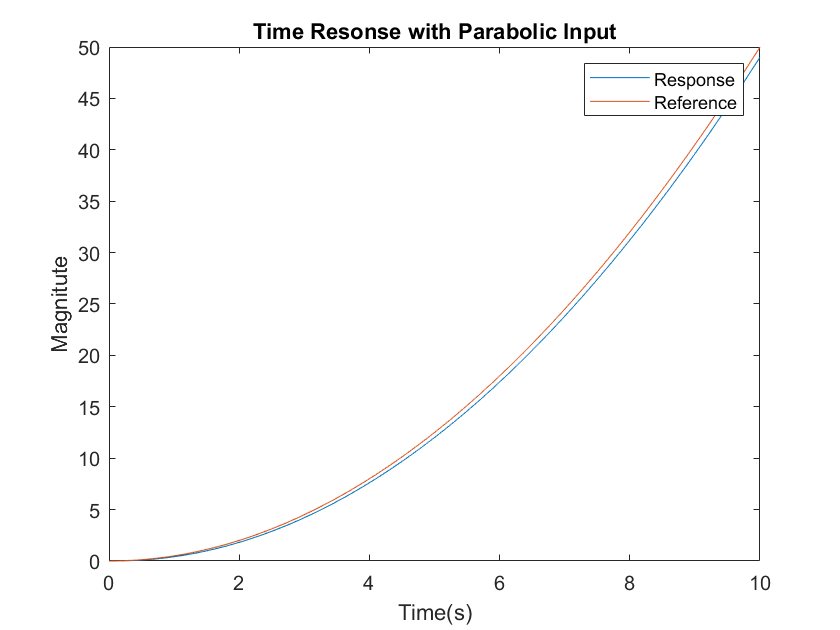


%Time Response of System
figure
fplot(c1,[0,10]);
hold on
fplot(r,[0,10]);
hold off
xlabel('Time(s)');
ylabel('Magnitute');
title('Time Resonse with Parabolic Input');
legend Response Reference;

# 4.4 Effect of Variation of Time Constant in First Order System


$$G\left(s\right)=\frac{1}{1+T\;s}$$


%Defining the System Parametera
T=0.8;

% Defining the System
syms s;
G1=1/(1+T*s);    

% For Different Inputs Signal 
A=1;
j=3;
R=A/s^j;
r=ilaplace(R);

% Output in s-Domain
C1=G1*R;
% Output in Time Domain
c1=ilaplace(C1)

$$c1 = \frac{t^{2}}{2}-\frac{16\,{\mathrm{e}}^{-\frac{5\,t}{4}}}{25}-\frac{4\,t}{5}+\frac{16}{25}$$

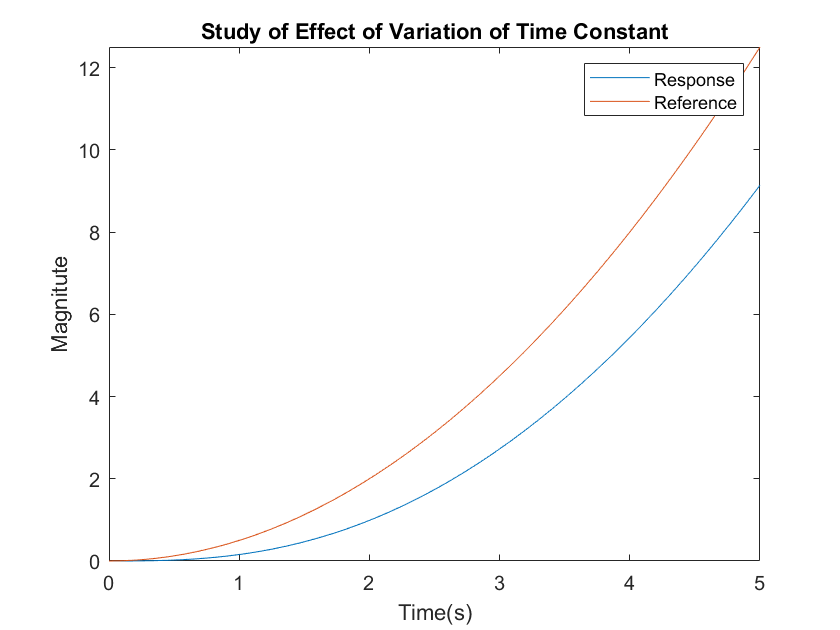


%Time Response of System
figure
fplot(c1,[0,5]);
hold on
fplot(r,[0,5]);
hold off
xlabel('Time(s)');
ylabel('Magnitute');
title('Study of Effect of Variation of Time Constant');
legend Response Reference;

%axis([2.1,2.3,16.8,17.1]);   % Zoom it to see

# 4.5 Effect of Variation of Pole's Location on Time Response


$$G\left(s\right)=\frac{1}{s+a}$$


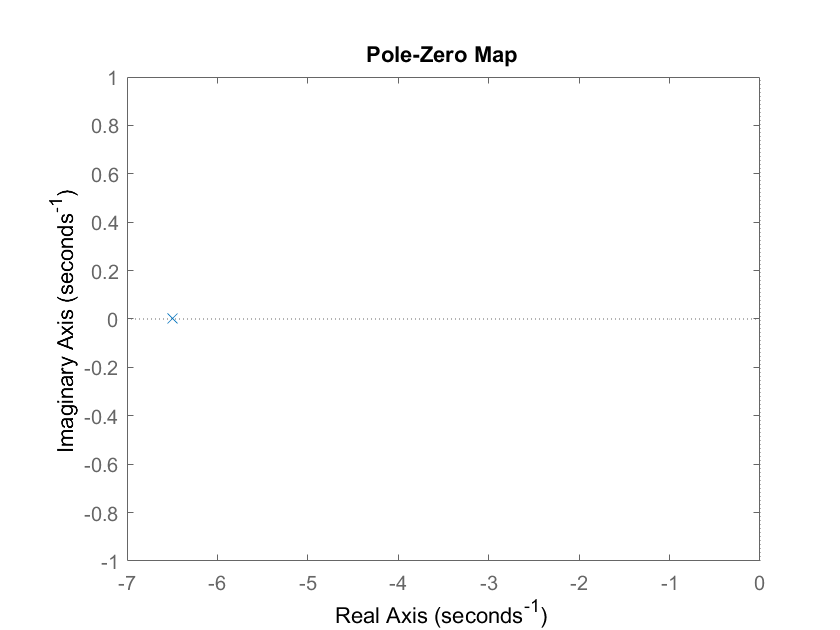

%Defining the System Parametera
a=6.5;
s=tf('s');
G=10/(s+a);
pzplot(G)

% Defining the System
syms s t;
G1=10/(s+a);   

% For Different Inputs Signal 
A=1;
j=1;
R=A/s^j;
r=ilaplace(R);

% Output in s-Domain
C1=G1*R;
% Output in Time Domain
c1=ilaplace(C1)

$$c1 = \frac{20}{13}-\frac{20\,{\mathrm{e}}^{-\frac{13\,t}{2}}}{13}$$

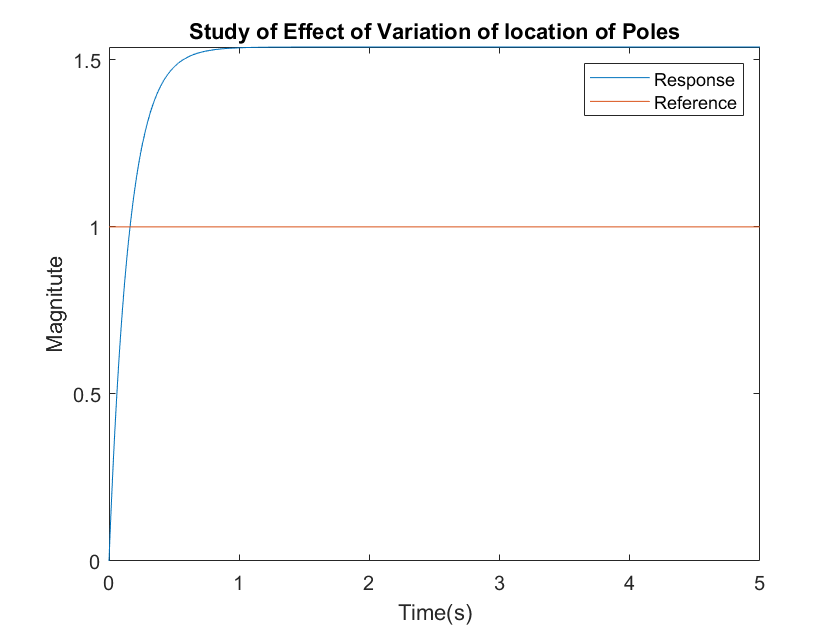


%Time Response of System
figure
fplot(c1,[0,5]);
hold on
fplot(r,[0,5]);
hold off
xlabel('Time(s)');
ylabel('Magnitute');
title('Study of Effect of Variation of location of Poles');
legend Response Reference;

# 4.6 Time Response of Second Order with different sources


$$G\left(s\right)=\frac{24}{s^2 +5s+24}$$


## 4.6.1 With Step Input

% Defining the System
syms s;
G1=24/(s^2+5*s+24);    % Refer Example 2 of Lecture 3.4

% For Step Signal 
A=14;
R=A/s;
r=ilaplace(R);

% Output in s-Domain
C1=G1*R;
% Output in Time Domain
c1=ilaplace(C1)

%Time Response of System
figure
fplot(c1,[0,10]);

$$c1 = 14-14\,{\mathrm{e}}^{-\frac{5\,t}{2}}\,\left(\cos\left(\frac{\sqrt{71}\,t}{2}\right)+\frac{5\,\sqrt{71}\,\sin\left(\frac{\sqrt{71}\,t}{2}\right)}{71}\right)$$

hold on
fplot(r,[0,10]);
hold off
xlabel('Time(s)');
ylabel('Magnitute');
title('Time Resonse with Step Input');
legend Response Reference;

## 4.6.2 With Ramp Input

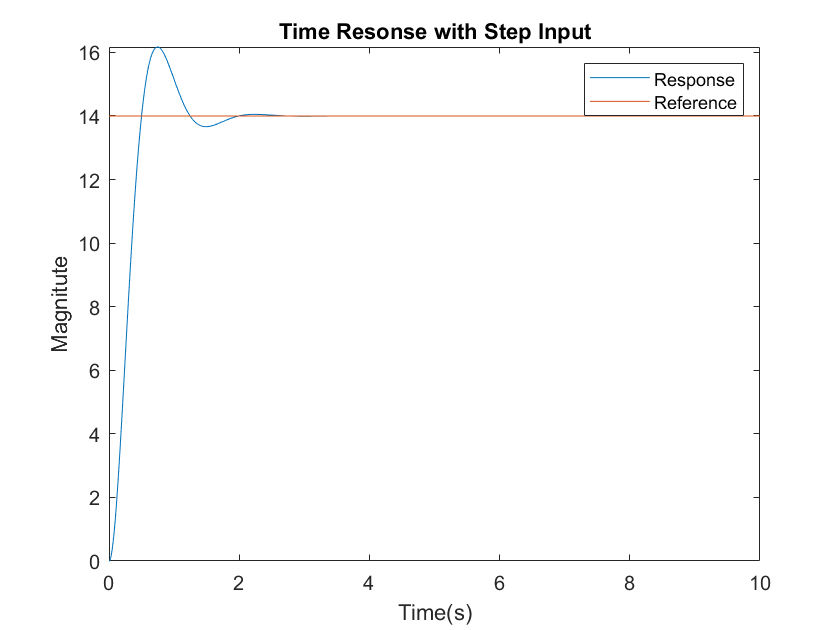

% Defining the System
syms s;
G1=24/(s^2+5*s+24);    % Refer Example 2 of Lecture 3.4


% For Ramp Signal 
A=4;
R=A/s^2;
r=ilaplace(R);

% Output in s-Domain
C1=G1*R;
% Output in Time Domain
c1=ilaplace(C1)

%Time Response of System
figure
fplot(c1,[0,20]);
hold on

$$c1 = 4\,t+\frac{5\,{\mathrm{e}}^{-\frac{5\,t}{2}}\,\left(\cos\left(\frac{\sqrt{71}\,t}{2}\right)-\frac{23\,\sqrt{71}\,\sin\left(\frac{\sqrt{71}\,t}{2}\right)}{355}\right)}{6}-\frac{5}{6}$$

fplot(r,[0,20]);
hold off
xlabel('Time(s)');
ylabel('Magnitute');
title('Time Resonse with Ramp Input');
legend Response Reference;

## 4.6.3 With Parabolic Input

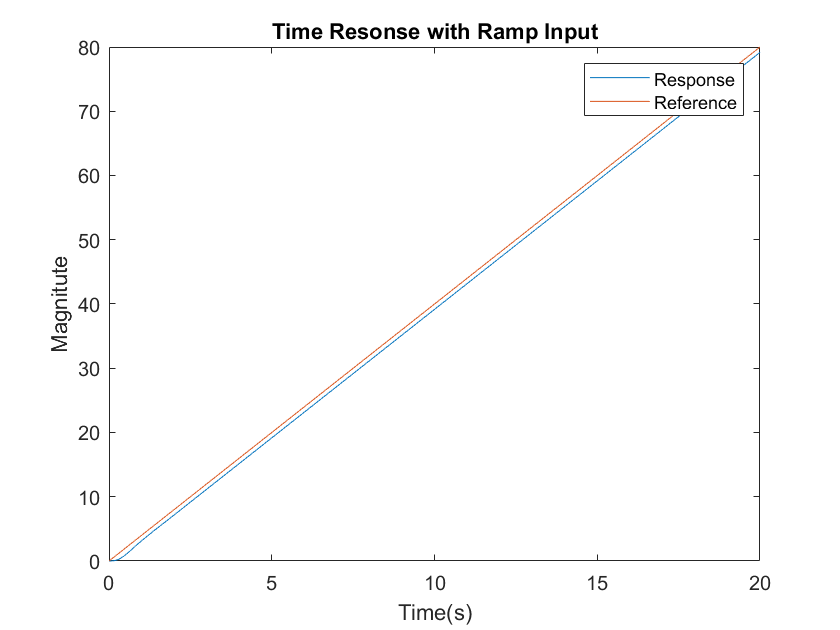

% Defining the System
syms s;
G1=24/(s^2+5*s+24);    % Refer Example 2 of Lecture 3.4

% For Parabolic Signal 

A=9;
R=A/s^3;
r=ilaplace(R);

% Output in s-Domain
C1=G1*R;
% Output in Time Domain
c1=ilaplace(C1)

%Time Response of System
figure
fplot(c1,[0,10]);
hold on
fplot(r,[0,10]);

$$c1 = \frac{9\,t^{2}}{2}-\frac{15\,t}{8}-\frac{{\mathrm{e}}^{-\frac{5\,t}{2}}\,\left(\cos\left(\frac{\sqrt{71}\,t}{2}\right)-\frac{235\,\sqrt{71}\,\sin\left(\frac{\sqrt{71}\,t}{2}\right)}{71}\right)}{64}+\frac{1}{64}$$

hold off
xlabel('Time(s)');
ylabel('Magnitute');
title('Time Resonse with Parabolic Input');
legend Response Reference;

# 4.7 Effect of Variation of Damping Ratio

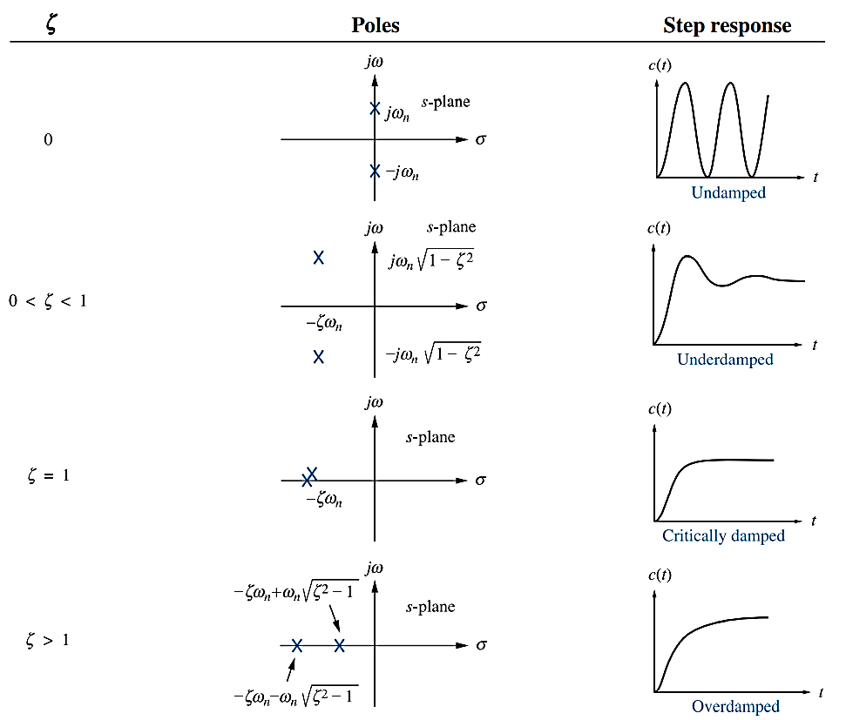

Fig: Effect of Variation of Damping Ratio [2]


$$G\left(s\right)=\frac{\omega_n^2 }{s^2 +2\xi \omega_n s+\omega_n^2 }$$


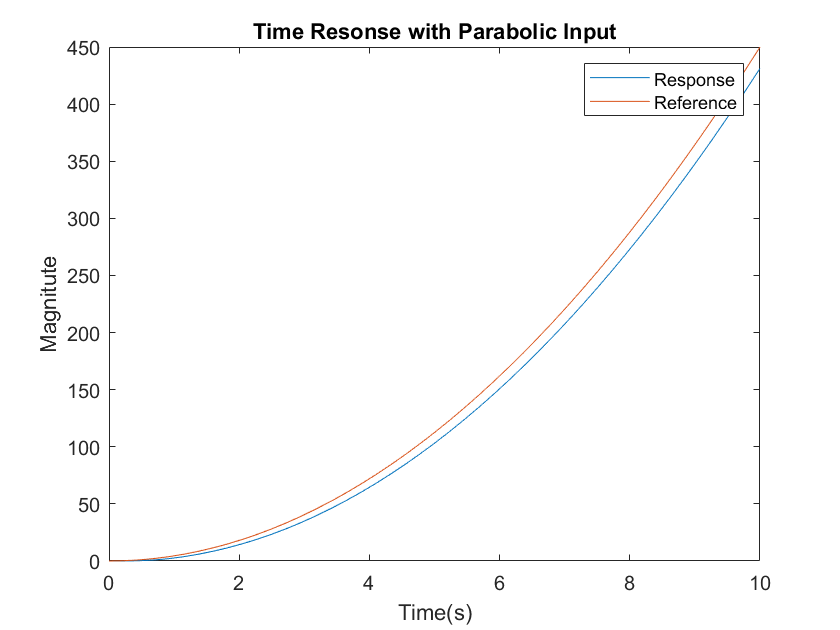

% Natural Frequency
w=10;   % Also Check for variation of Wn
% Damping Ratio
Z=1.5;

% Defining the System

syms s;
G2=w^2/(s^2+2*Z*w*s+w^2);


% For Step Signal 
A=2;
R=A/s;

%Response in Time Domain
r=ilaplace(R);

% Output in s-Domain
C2=G2*R;
% Output in Time Domain
c2=ilaplace(C2)
%Time Response of System
figure
fplot(c2,[0,10]);
hold on
fplot(r,[0,10]);
hold off

# 4.8 Effect of Addition of Zeros on Time Response

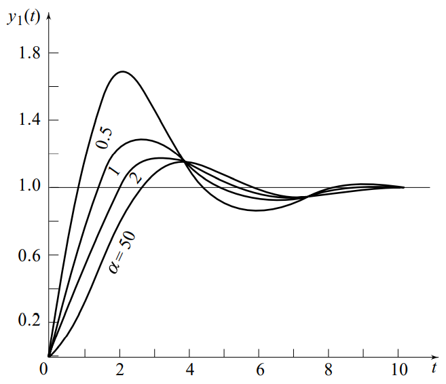

Fig: Effect of Addition of Zeros[2]


$$G\left(s\right)=\frac{\omega_n^2 }{s^2 +2\xi \omega_n s+\omega_n^2 }$$


% Natural Frequency
w=10;
% Damping Ratio
Z=0.3;

$$c2 = 2-2\,{\mathrm{e}}^{-15\,t}\,\left(\cosh\left(5\,\sqrt{5}\,t\right)+\frac{3\,\sqrt{5}\,\sinh\left(5\,\sqrt{5}\,t\right)}{5}\right)$$

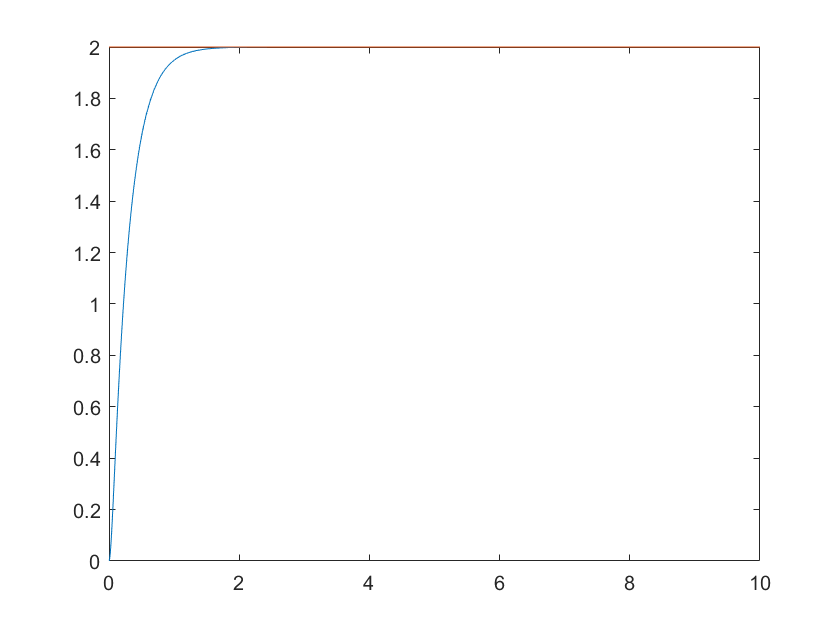

% Variable for Variation of Zeros
a=20;

%FOr Plotting in P_Z Plane
s=tf('s');
G2S=w^2/(s^2+2*Z*w*s+w^2);

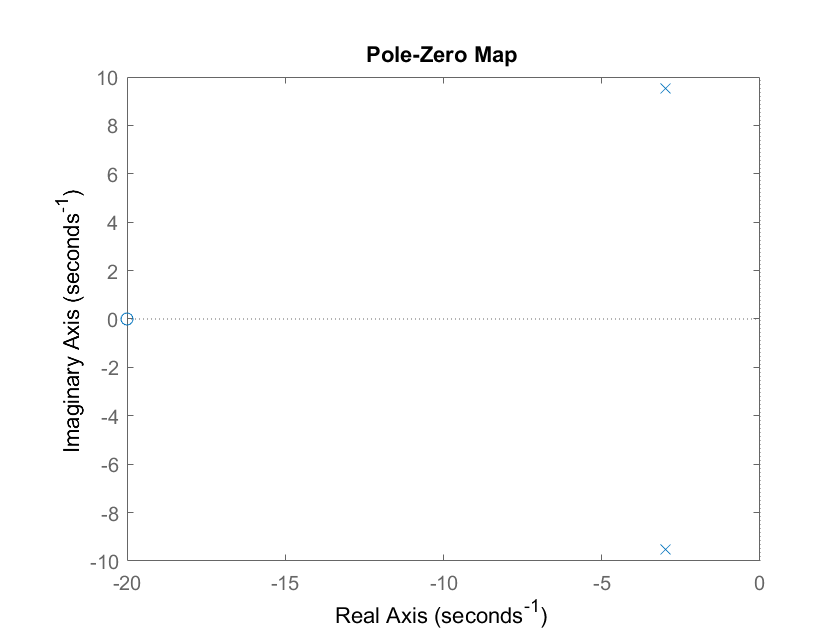

Za=(s+a)/a;
G=G2S*Za;
pzplot(G)

% Defining the System
syms s;
G1=w^2/(s^2+2*Z*w*s+w^2);

% Assign Zeros to the System
G2S=w^2/(s^2+2*Z*w*s+w^2);
Za=(s+a)/a;   % Noramlized Zero
G2=G2S*Za;     % Zero Addition

% For Different Inputs Signal 
A=1;
j=1;
R=A/s^j;
r=ilaplace(R);


% Output in s-Domain
C1=G1*R;
C2=G2*R;
D=s*C1;
% Output in Time Domain
c1=ilaplace(C1)
c2=ilaplace(C2)
d=ilaplace(D)
%Time Response of System
figure
fplot(c1,[0,5]);
hold on
fplot(r,[0,5]);
fplot(c2,[0,5]);
%fplot(d,[0,5]);
hold off
xlabel('Time(s)');
ylabel('Magnitute');
title('Study of Effect of Addition of Zeros');
legend Before-adding-Zero Reference After-Adding-Zero ;

# 4.9 Effect of Addition of Poles on Time Response

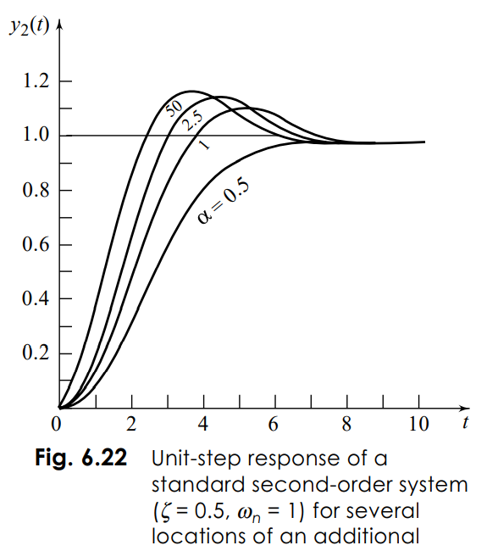

Fig: Effect of Addition of Poles[2]


$$G\left(s\right)=\frac{\omega_n^2 }{s^2 +2\xi \omega_n s+\omega_n^2 }*\frac{a}{s+a}$$


% Natural Frequency
w=10;

$$c1 = 1-{\mathrm{e}}^{-3\,t}\,\left(\cos\left(\sqrt{91}\,t\right)+\frac{3\,\sqrt{91}\,\sin\left(\sqrt{91}\,t\right)}{91}\right)$$

% Damping Ratio

$$c2 = 1-{\mathrm{e}}^{-3\,t}\,\left(\cos\left(\sqrt{91}\,t\right)-\frac{2\,\sqrt{91}\,\sin\left(\sqrt{91}\,t\right)}{91}\right)$$

Z=0.3;

$$d = \frac{100\,\sqrt{91}\,{\mathrm{e}}^{-3\,t}\,\sin\left(\sqrt{91}\,t\right)}{91}$$

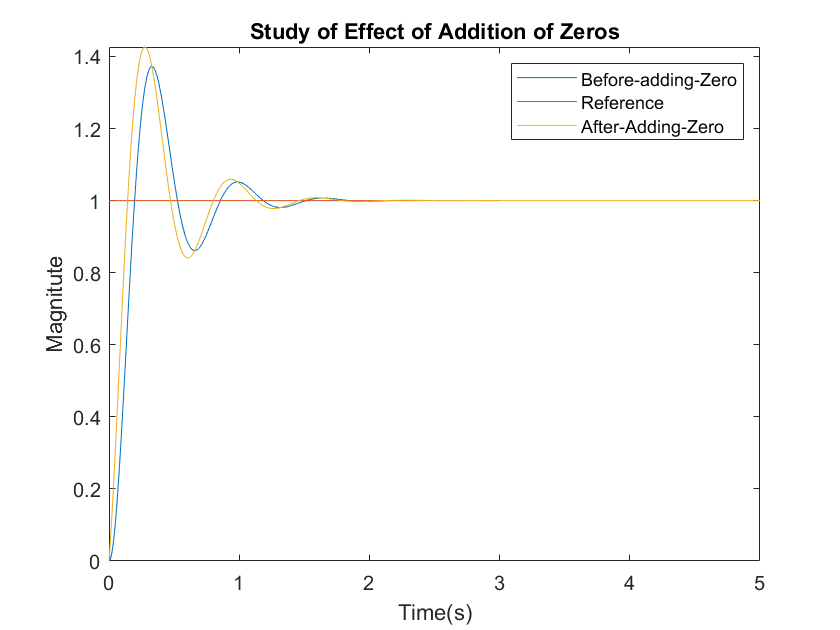

% Variable for Variation of Zeros
a=1;

%FOr Plotting in P_Z Plane
s=tf('s');
G2S=w^2/(s^2+2*Z*w*s+w^2);
Za=a/(s+a);
G=G2S*Za;
pzplot(G)

% Defining the System
syms s;

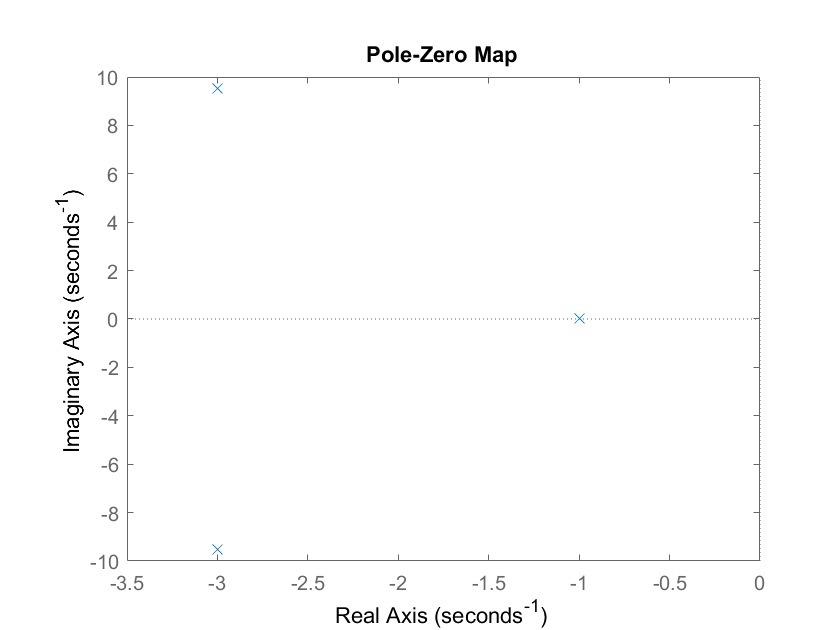

G1=w^2/(s^2+2*Z*w*s+w^2);

% Assign Zeros to the System
G2S=w^2/(s^2+2*Z*w*s+w^2);
Za=a/(s+a);   % Noramlized Pole
G2=G2S*Za;     % Pole Addition

% For Different Inputs Signal 
A=1;
j=1;
R=A/s^j;
r=ilaplace(R);

% Output in s-Domain
C1=G1*R;
C2=G2*R;
% Output in Time Domain
c1=ilaplace(C1)
c2=ilaplace(C2)

%Time Response of System
figure
fplot(c1,[0,5]);
hold on
fplot(r,[0,5]);
fplot(c2,[0,5]);
hold off
xlabel('Time(s)');
ylabel('Magnitute');
title('Study of Effect of Addition of Poles');
legend Before-adding-Poles Reference After-Adding-Poles ;

# 4.10 What about Dominating Poles?

If ratio of real part of one pole is greater than 5 times the other than we can say the former one is dominant poles. SImilar case is with Poles and Zeros. They are nearer to the Origin.

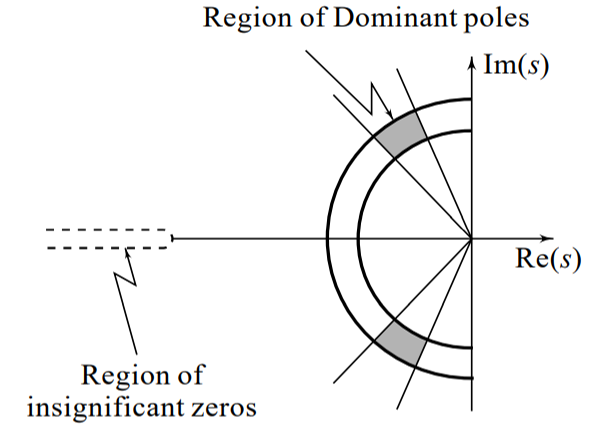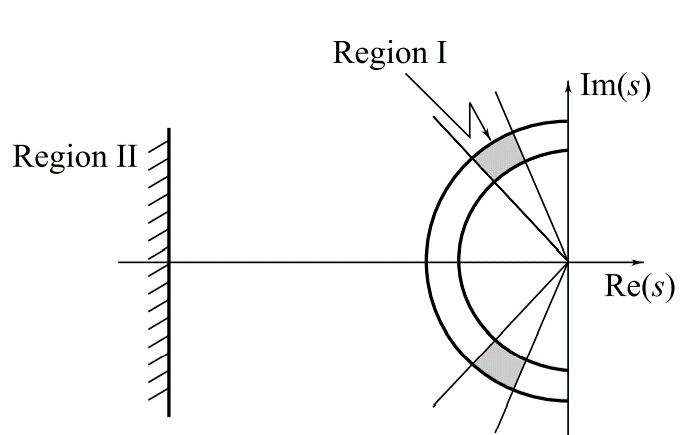

Fig: Dominant Poles with Zeros and Other Poles [2]

# 4.11 Transient Response Specfications


$$G\left(s\right)=\frac{\omega_n^2 }{s^2 +2\xi \omega_n s+\omega_n^2 }$$


% Natural Frequency
w=6;
% Damping Ratio
Z=0.06;

% Defining the System
num=w^2;
den=[1 2*Z*w w^2];
G=tf(num,den);
% To Plot Step Function Response

$$c1 = 1-{\mathrm{e}}^{-3\,t}\,\left(\cos\left(\sqrt{91}\,t\right)+\frac{3\,\sqrt{91}\,\sin\left(\sqrt{91}\,t\right)}{91}\right)$$

step(G)

$$c2 = \frac{{\mathrm{e}}^{-3\,t}\,\left(\cos\left(\sqrt{91}\,t\right)-\frac{17\,\sqrt{91}\,\sin\left(\sqrt{91}\,t\right)}{91}\right)}{19}-\frac{20\,{\mathrm{e}}^{-t}}{19}+1$$

%To Get Transient Response Data
S=stepinfo(G)
S.RiseTime
% Defining Settling Threshods
S1 = stepinfo(G,'SettlingTimeThreshold',0.005);
st1 = S1.SettlingTime

# 4.12 Working with DC Motor

## 4.12.1 DC Motor Position Control in Script

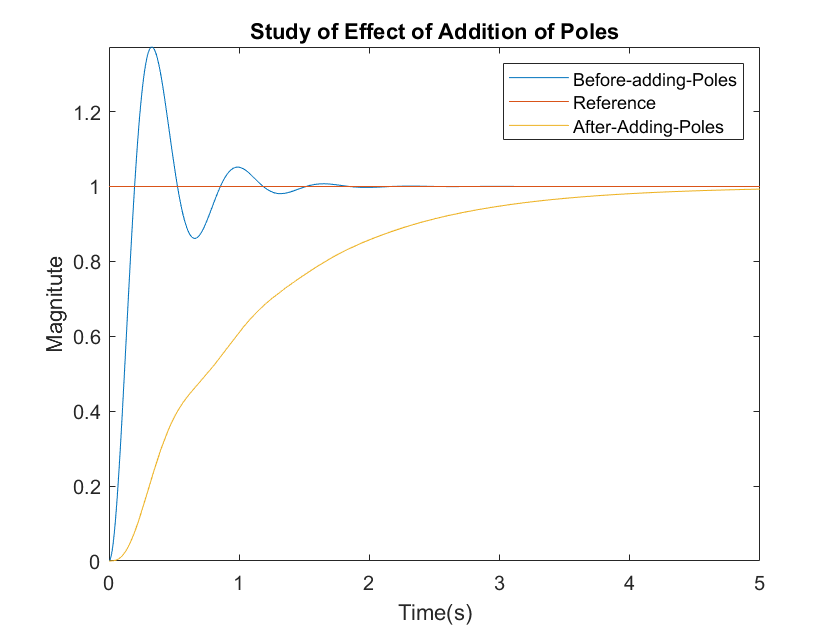

J = 3.2284E-6;
b = 3.5077E-6;
K = 0.0274;
R = 4;
L = 2.75E-6;

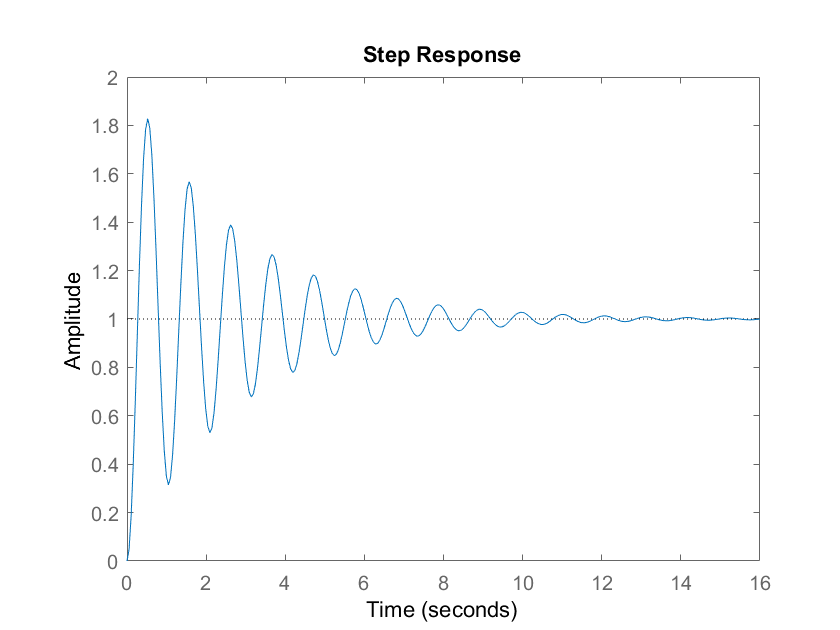

S = struct with fields:
        RiseTime: 0.1820
    SettlingTime: 10.5765
     SettlingMin: 0.3146
     SettlingMax: 1.8279
       Overshoot: 82.7909
      Undershoot: 0
            Peak: 1.8279
        PeakTime: 0.5236


ans = 0.1820

st1 = 14.2632

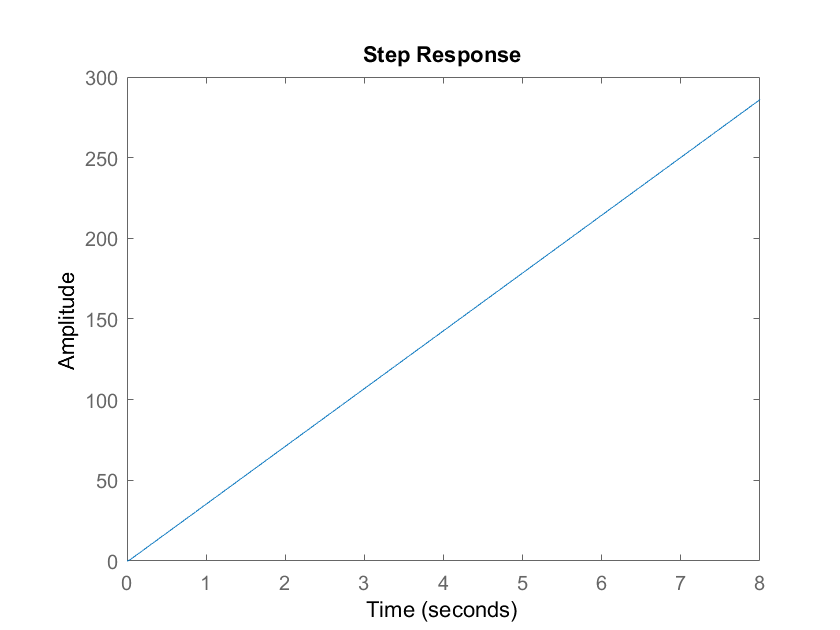

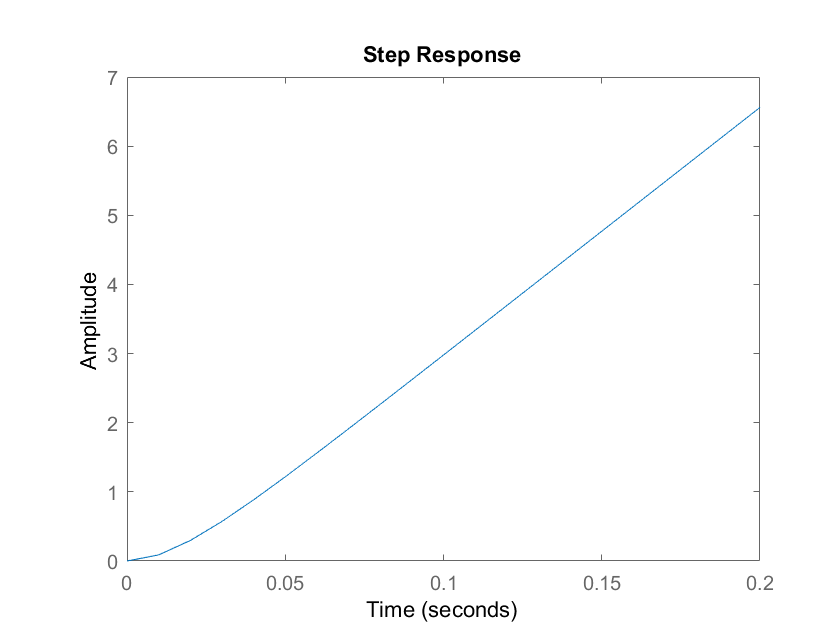

ans = logical
   0


ans = 	1.0e+06 *

         0
   -1.4545
   -0.0001


s = tf('s');
Pos_motor = K/(s*((J*s+b)*(L*s+R)+K^2));

step(Pos_motor)

t=0:0.01:0.2;
step(Pos_motor,t)

## 4.12.2 DC Motor Position Control in Simulink

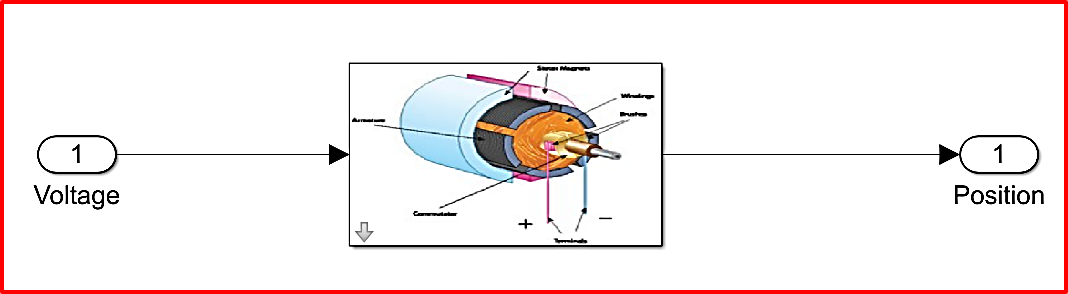

Fig: Simulink Model of DC Motor

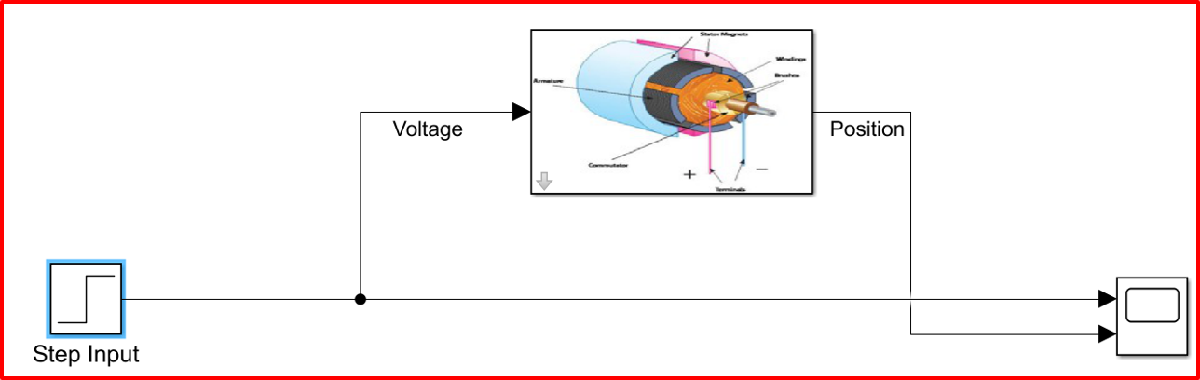

Fig: DC Motor with Step Input

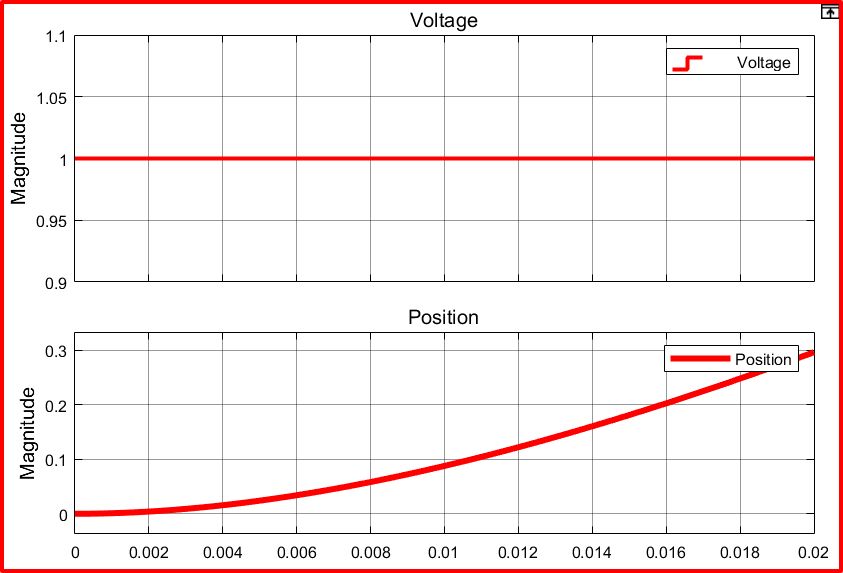

Fig: Time Response of Unit Step Input of Position Control DC Motor

# References

- Mathworks.inc

- Nise, Norman S. "Control system engineering, John Wiley & Sons." *Inc, New York*(2011).

- [https://ctms.engin.umich.edu/CTMS/index.php?aux=Home](https://ctms.engin.umich.edu/CTMS/index.php?aux=Home)

- Bakshi, Uday A., and Varsha U. Bakshi. *Control system engineering*. Technical Publications, 2020.